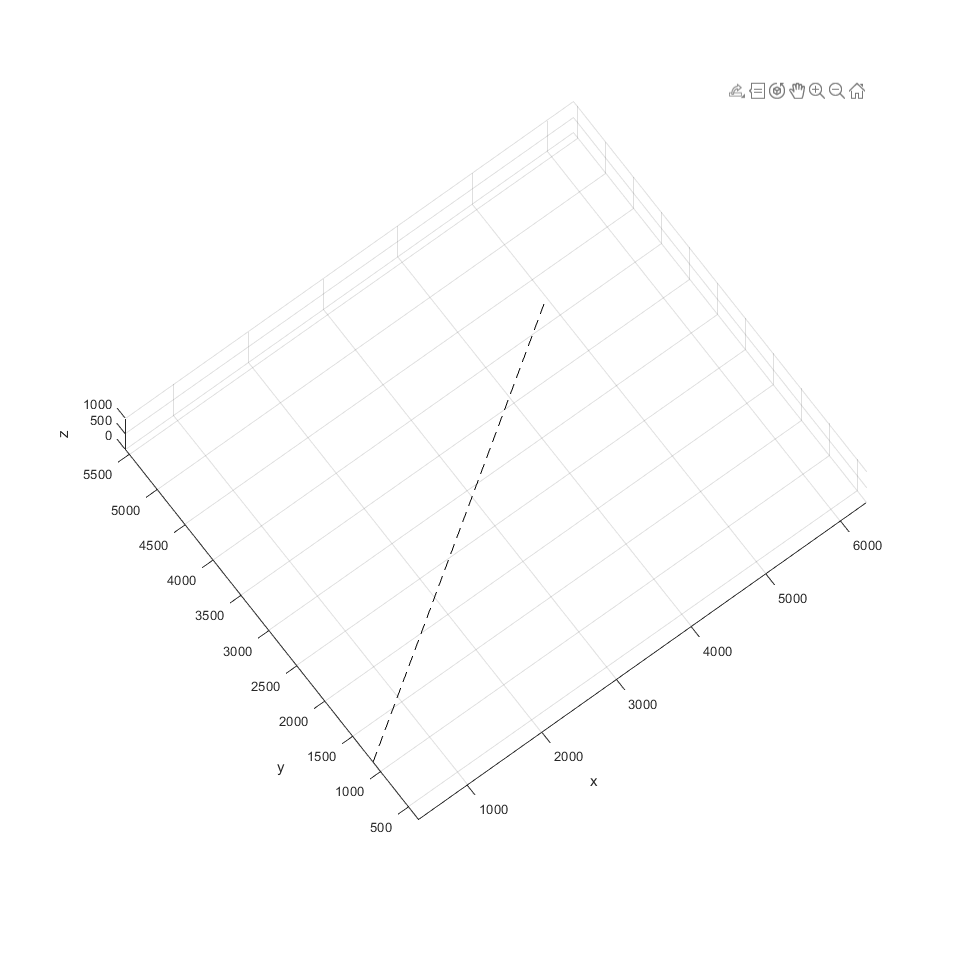

clearvars;
FigSetup();

global currentPathPoint PosX PosY PosZ theta1 theta2 theta3 OG_theta1 cnst bodyTwist H PosX_W3 PosY_W3 PosX_W4 PosY_W4 PosZ_W3 BH X0W Y0W mode legRotation bodyAngle currentPathPoint_w vari bodyTurn a inpt currentPathPoint_t currentPathPoint_tw flag;

currentPathPoint = [4;10;4;10;4;10]; currentPathPoint_w = [4,10]; currentPathPoint_t = [1,1]; currentPathPoint_tw = [2,2];
PosX = zeros(6,1); PosY = zeros(6,1); PosZ = zeros(6,1);
theta1 = zeros(6,1); theta2 = zeros(6,1); theta3 = zeros(6,1); OG_theta1 = zeros(6,1);
cnst = struct;
bodyTwist = 0;
PosX_W3 = 0; PosY_W3 = 0; PosZ_W3 = BH; PosX_W4 = 0; PosY_W4 = 0;
H = 0;
X0W = 0; Y0W = 0;
mode = "";
legRotation = 0; bodyAngle = 0; bodyTurn = 0; 

vari.Ss = 100; vari.Sh = 50; vari.Rd = 283.71;   %Stride length; Step hight; Radial distance
vari.dir = -0*pi/180; %Walking direction
BH = 140.0000;   %Body height
vari.p = 0; vari.r = 0; %Body pitch and roll angle

cnst.B = 125.54; %hexapod body radius

%Rotation angle relative to global axis
cnst.rot = [0*pi/180, 60*pi/180, 120*pi/180, 180*pi/180, 240*pi/180, 300*pi/180];

%From leg to body coordinate 
cnst.XG = @(x,y,alp) y*sin(alp)+(x+cnst.B)*cos(alp);
cnst.YG = @(x,y,alp) y*cos(alp)-(x+cnst.B)*sin(alp);

%Transform body to leg coordinate
cnst.XL = @(xp,yp,rot) xp*cos(rot) - yp*sin(rot) - cnst.B;
cnst.YL = @(xp,yp,rot) xp*sin(rot) + yp*cos(rot);

%Create path for each leg
[xp,yp,zp] = makepathCombined(vari.Rd,vari.dir,vari.Ss,vari.Sh,vari.p,vari.r,bodyAngle);

%Insert a input here to give a command
[indx,tf] = listdlg('PromptString',{'Select a mode'},"SelectionMode","single","ListString",{'stand','walk','turn','twist','turn_walk','waypoint navigate'});

j = 0; ang = 0; ang1 = 120; turnAng = 0;
while 1
    if j <= 5
        SetPosition([283.71;141.855;-141.855;-283.71;-141.855;141.855],[0;-245.7;-245.7;0;245.7;245.7],[-BH;-BH;-BH;-BH;-BH;-BH])% home stance
        Display_moving_hex();        
    else
       if tf == 1 && indx == 1 %stand
            mode = "stand";
            SetPosition([283.71;141.855;-141.855;-283.71;-141.855;141.855],[0;-245.7;-245.7;0;245.7;245.7],[-BH;-BH;-BH;-BH;-BH;-BH])% home stance
            Display_moving_hex();   
            [indx,tf] = listdlg('PromptString',{'Select a mode'},"SelectionMode","single","ListString",{'stand','walk','turn','twist','turn_walk','waypoint navigate'});
            
        elseif tf == 1 && indx == 2 %walk
            distance = str2double(inputdlg('Enter walking distance [mm]:','Input',[1 35],{'200'}));
            flag = 1;
            for i = 1:(13*distance/(vari.Ss*2))
                setNextPathPoint(xp,yp,zp);
                Display_moving_hex();
            end           
            indx = 1;
            
        elseif tf == 1 && indx == 3 %turn
            angle = str2double(inputdlg('Enter turning angle:','Input',[1 35],{'30'}));
            %tbAng = vari.Ss/(sqrt(cnst.XL(PosX(1),PosY(1),cnst.rot(1))^2+cnst.YL(PosX(1),PosY(1),cnst.rot(1))^2))*180/pi;
            tbAng = 15;
            tp = TurnPath(0,0,tbAng,15);
            [a,z] = tp.MakePath("turn");
            
            for turnAng = tbAng:tbAng:abs(angle)
                for i = 1:13
                    if angle>=0
                        turnbody(-a*pi/180,z,"absolute");
                    else
                        turnbody(a*pi/180,z,"absolute");
                    end
                    %flag = 1;
                    Display_moving_hex(); 
                end
            end
            indx = 1;
           
        elseif tf == 1 && indx == 4 %twist
            angle = str2double(inputdlg('Enter twisting angle (max 30):','Input',[1 35],{'30'}));
            for ang = 0:5:abs(angle)
                if angle>=0
                    twistbody(-ang*pi/180);
                else
                    twistbody(ang*pi/180);
                end
                Display_moving_hex();                
            end
            indx = 1;
            
        elseif tf == 1 && indx == 5 %turn_walk
            inpt = str2double(inputdlg({'Enter distance [mm]:','Enter angle:'},'Input',[1 35],{'200','30'}));
            tp = TurnPath(0,0,inpt(2),15);
            a = tp.MakePath("turnwalk");
            
            for i = 1:4
                setNextPathPoint(xp,yp,zp);
                Display_moving_hex();
            end
            
            flag = 0;
            for i = 1:(12*(inpt(1))/(vari.Ss*2))
                setNextPathPoint(xp,yp,zp);
                if inpt(2)>=0
                    turnwalk(-a*pi/180);
                else
                    turnwalk(a*pi/180);
                end
                Display_moving_hex();   
            end
            
            for i = 1:3
                setNextPathPoint(xp,yp,zp);
                Display_moving_hex();
            end
            currentPathPoint = [4;10;4;10;4;10];
            currentPathPoint_w = [4,10];
            indx = 1;
            
        elseif tf == 1 && indx == 6 %waypoint navigate
            Esrc = 150; Nsrc = 1000;
            Edest = 5000; Ndest = 4250;
            line([Esrc Edest],[Nsrc Ndest],[0 0],'color','black','LineStyle','--')            
            Head_t = atan((Edest-Esrc)/(Ndest-Nsrc));
            L_t = sqrt((Ndest-Nsrc)^2+(Edest-Esrc)^2);
            V_hex = vari.Ss/1000/2; %Ss[m]/tf[s]
            
            [ct] = [cos(Head_t) sin(Head_t);-sin(Head_t) cos(Head_t)]*[Y0W-Nsrc;X0W-Esrc];
            ct_dist = ct(1);
            ct_err = ct(2);
            while ct_dist < L_t
                %Head_hex = pi/2 - bodyAngle;
                Head_hex = pi/2 + vari.dir;
                
                %ct_err_d = V_hex*(Head_hex-Head_t);
                %ct_err = integrate ct_err_d;
                
                ct_err_ref = 0;
                err_ref = ct_err_ref - ct_err;
                Ky = 0.0007;
                Head_ref = Head_t + Ky*(err_ref);
                vari.dir = Head_ref - pi/2; 
                
                %do a turnwalk with Head_ref (will cause bodyAngle to change, therefore Head_hex changes)
                [xp,yp,zp] = makepathCombined(vari.Rd,vari.dir,vari.Ss,vari.Sh,vari.p,vari.r,0); % Sal later turnwalk gebruik, gaan eers crab walk
                for i = 1:13
                    setNextPathPoint(xp,yp,zp);
                    Display_moving_hex();
                end
                [ct] = [cos(Head_t) sin(Head_t);-sin(Head_t) cos(Head_t)]*[Y0W-Nsrc;X0W-Esrc];
                ct_dist = ct(1);
                ct_err = ct(2);                
                %restart loop
            end
            
            indx = 1;
        end 
    end 
    j = j + 1;       
end

function FigSetup()

    %Figure setup
    F = figure;
    % Ax = axes('CameraPosition',[10 -10 10]);
    xlabel('x'); ylabel('y'); zlabel('z');
    grid on
    axis("equal")
    set(F, 'visible','on')
    
    %Zero point
    line([0 0],[0 0],[-5 12], 'color', 'black', 'LineStyle',"--");
    line([0 12],[0 0],[0 0], 'color', 'black', 'LineStyle',"--");
    line([0 0],[0 12],[0 0], 'color', 'black', 'LineStyle',"--");
    
    view(3);
    xlim([-1000 1000]);
    ylim([-1000 1000]);
    zlim([0 1000]);
    
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [link1,link2,link3] = makeleg(x01,y01,z01,x02,y02,z02,x03,y03,z03,rot,leg)
    global cnst H BH X0W Y0W bodyAngle;
    %Local to body to world coor
    xg01 = cnst.XG(x01, y01,rot);
    yg01 = cnst.YG(x01, y01,rot);
    zw01 = z01;
    xg02 = cnst.XG(x02, y02,rot);
    yg02 = cnst.YG(x02, y02,rot);
    zw02 = z02;
    xg03 = cnst.XG(x03, y03,rot);
    yg03 = cnst.YG(x03, y03,rot);
    zw03 = z03;
        
    xw01 = xg01*cos(bodyAngle)-yg01*sin(bodyAngle)+X0W;
    yw01 = xg01*sin(bodyAngle)+yg01*cos(bodyAngle)+Y0W;
    xw02 = xg02*cos(bodyAngle)-yg02*sin(bodyAngle)+X0W;
    yw02 = xg02*sin(bodyAngle)+yg02*cos(bodyAngle)+Y0W;
    xw03 = xg03*cos(bodyAngle)-yg03*sin(bodyAngle)+X0W;
    yw03 = xg03*sin(bodyAngle)+yg03*cos(bodyAngle)+Y0W;         

    link1 = line([H(1,leg) xw01],[H(2,leg) yw01],[BH zw01+BH]);
    link2 = line([xw01 xw02],[yw01 yw02],[zw01+BH zw02+BH]);
    link3 = line([xw02 xw03],[yw02 yw03],[zw02+BH zw03+BH]);
    set(link1, 'color', 'red');
    set(link2, 'color', 'green');
    set(link3, 'color', 'blue');
    
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [BodyLine] = DrawHexapod() 
    global cnst BH H X0W Y0W bodyAngle;   
    BodyLine = zeros(6,1); H_temp = zeros(2,7);
    %Hexapod
    H = [cnst.B, cnst.B*sind(30), -cnst.B*sind(30), -cnst.B, -cnst.B*sind(30), cnst.B*sind(30), cnst.B;    %x
            0, -cnst.B*cosd(30), -cnst.B*cosd(30), 0, cnst.B*cosd(30), cnst.B*cosd(30), 0];    %y
    
    for i=1:7
        H_temp(1,i) = H(1,i)*cos(bodyAngle)-H(2,i)*sin(bodyAngle);
        H_temp(2,i) = H(1,i)*sin(bodyAngle)+H(2,i)*cos(bodyAngle);
    end
    H = H_temp;
    
    H = H + [X0W;Y0W]; 
    for i = 1:6 
        BodyLine(i) = line([H(1,i) H(1,i+1)],[H(2,i) H(2,i+1)],[BH BH]);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function Display_moving_hex()
    %Displaying moving legs
     
    global theta1 theta2 theta3 cnst legRotation PosX_W3 PosY_W3 PosX_W4 PosY_W4 PosX PosY PosZ X0W Y0W mode bodyTwist bodyAngle OG_bodyAngle currentPathPoint_w bodyTurn checker BH x_t y_t flag;
    
    if mode=="" 
        if PosZ(3) == -BH
            X0W = PosX_W3 -(PosX(3)); %%%%%%%%%%%%%%%%%%%
            Y0W = PosY_W3 -(PosY(3)); %%%%%%%%%%%%%%%%%%%
            PosX_W4 = PosX(4)*cos(bodyAngle)-PosY(4)*sin(bodyAngle)+X0W;
            PosY_W4 = PosX(4)*sin(bodyAngle)+PosY(4)*cos(bodyAngle)+Y0W;             
        elseif PosZ(4) == -BH
            X0W = PosX_W4 -(PosX(4)); %%%%%%%%%%%%%%%%%%%
            Y0W = PosY_W4 -(PosY(4)); %%%%%%%%%%%%%%%%%%% 
            PosX_W3 = PosX(3)*cos(bodyAngle)-PosY(3)*sin(bodyAngle)+X0W;
            PosY_W3 = PosX(3)*sin(bodyAngle)+PosY(3)*cos(bodyAngle)+Y0W;             
        end
    end
    
    if mode == "stand"
        legRotation = bodyTwist;
    end
    
    if mode=="twist"
        %bodyAngle = -fzero(@(x)(bodyTwist - (asin(cnst.B*sin(x)/sqrt(x03(1)^2+y03(1)^2)))-x),0.5);
        bodyAngle = -bodyTwist/2;
    elseif mode == "turn" || mode == "turnwalk"
        if checker == 1
            %bodyAngle = -fzero(@(x)(bodyTurn - (asin(cnst.B*sin(x)/sqrt(x03(1)^2+y03(1)^2)))-x),0.5);
            bodyAngle = OG_bodyAngle-bodyTurn/2;
        elseif checker == 0
            bodyAngle =  bodyAngle-bodyTurn/2;          
        end
    end 
    
    if flag
        PosX_W4 = PosX(4)*cos(bodyAngle)-PosY(4)*sin(bodyAngle)+X0W;
        PosY_W4 = PosX(4)*sin(bodyAngle)+PosY(4)*cos(bodyAngle)+Y0W;
        flag = 0;
    end
    
    x_t(1) = PosX(3)*cos(bodyAngle)-PosY(3)*sin(bodyAngle);
    y_t(1) = PosX(3)*sin(bodyAngle)+PosY(3)*cos(bodyAngle);
    x_t(2) = PosX(4)*cos(bodyAngle)-PosY(4)*sin(bodyAngle);
    y_t(2) = PosX(4)*sin(bodyAngle)+PosY(4)*cos(bodyAngle);    
    
    if mode == "walk" || mode == "turnwalk"
        %for walk displaying 
        if round(PosZ(3)) == -BH && currentPathPoint_w(2) ~= 1
            X0W = PosX_W3 -(x_t(1)); %%%%%%%%%%%%%%%%%%%
            Y0W = PosY_W3 -(y_t(1)); %%%%%%%%%%%%%%%%%%%
            PosX_W4 = PosX(4)*cos(bodyAngle)-PosY(4)*sin(bodyAngle)+X0W;
            PosY_W4 = PosX(4)*sin(bodyAngle)+PosY(4)*cos(bodyAngle)+Y0W;
        end
        if round(PosZ(4)) == -BH && currentPathPoint_w(1) ~= 1
            X0W = PosX_W4 -(x_t(2)); %%%%%%%%%%%%%%%%%%%
            Y0W = PosY_W4 -(y_t(2)); %%%%%%%%%%%%%%%%%%% 
            PosX_W3 = PosX(3)*cos(bodyAngle)-PosY(3)*sin(bodyAngle)+X0W;
            PosY_W3 = PosX(3)*sin(bodyAngle)+PosY(3)*cos(bodyAngle)+Y0W;              
        end
        
        for j = 1:2
            if currentPathPoint_w(j) == 12
                currentPathPoint_w(j) = 1;
            else
                currentPathPoint_w(j) = currentPathPoint_w(j) + 1;
            end
        end
    end  
           
    x01 = zeros(6,1); y01 = zeros(6,1); z01 = zeros(6,1);
    x02 = zeros(6,1); y02 = zeros(6,1); z02 = zeros(6,1);
    x03 = zeros(6,1); y03 = zeros(6,1); z03 = zeros(6,1);
    for i = 1:6
        [x01(i),y01(i),z01(i)] = FK01(theta1(i)+legRotation);       
        [x02(i),y02(i),z02(i)] = FK02(theta1(i)+legRotation,theta2(i));
        [x03(i),y03(i),z03(i)] = FK03(theta1(i)+legRotation,theta2(i),theta3(i));
    end
        
    BodyLine = DrawHexapod();
        
    [link1,link2,link3] = makeleg(x01(1),y01(1),z01(1),x02(1),y02(1),z02(1),x03(1),y03(1),z03(1),cnst.rot(1),1);
    [link4,link5,link6] = makeleg(x01(2),y01(2),z01(2),x02(2),y02(2),z02(2),x03(2),y03(2),z03(2),cnst.rot(2),2);
    [link7,link8,link9] = makeleg(x01(3),y01(3),z01(3),x02(3),y02(3),z02(3),x03(3),y03(3),z03(3),cnst.rot(3),3);
    [link10,link11,link12] = makeleg(x01(4),y01(4),z01(4),x02(4),y02(4),z02(4),x03(4),y03(4),z03(4),cnst.rot(4),4);
    [link13,link14,link15] = makeleg(x01(5),y01(5),z01(5),x02(5),y02(5),z02(5),x03(5),y03(5),z03(5),cnst.rot(5),5);
    [link16,link17,link18] = makeleg(x01(6),y01(6),z01(6),x02(6),y02(6),z02(6),x03(6),y03(6),z03(6),cnst.rot(6),6);
                    
    pause(0.1);
    delete(BodyLine(1));delete(BodyLine(2));delete(BodyLine(3));delete(BodyLine(4));delete(BodyLine(5));delete(BodyLine(6));
    delete(link1);delete(link2);delete(link3);
    delete(link4);delete(link5);delete(link6);
    delete(link7);delete(link8);delete(link9);
    delete(link10);delete(link11);delete(link12);
    delete(link13);delete(link14);delete(link15);
    delete(link16);delete(link17);delete(link18);    
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [xp,yp,zp] = makepathCombined(Rd,dir,Ss,Sh,p,r,bodyAngl)
    global cnst BH;
    %Create path for each leg
    [xp(1,:),yp(1,:),zp(1,:)] = makepath(Rd,dir,Ss,Sh,BH,cnst.rot(1),p,r,bodyAngl);
    [xp(2,:),yp(2,:),zp(2,:)] = makepath(Rd,dir,Ss,Sh,BH,cnst.rot(2),p,r,bodyAngl);
    [xp(3,:),yp(3,:),zp(3,:)] = makepath(Rd,dir,Ss,Sh,BH,cnst.rot(3),p,r,bodyAngl);
    [xp(4,:),yp(4,:),zp(4,:)] = makepath(Rd,dir,Ss,Sh,BH,cnst.rot(4),p,r,bodyAngl);
    [xp(5,:),yp(5,:),zp(5,:)] = makepath(Rd,dir,Ss,Sh,BH,cnst.rot(5),p,r,bodyAngl);
    [xp(6,:),yp(6,:),zp(6,:)] = makepath(Rd,dir,Ss,Sh,BH,cnst.rot(6),p,r,bodyAngl);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function setNextPathPoint(xp,yp,zp)

    global currentPathPoint; global PosX; global PosY; global PosZ; global theta1; global theta2; global theta3 mode;

    mode = "walk";
    
    for i = 1:6
        PosX(i) = xp(i,currentPathPoint(i));
        PosY(i) = yp(i,currentPathPoint(i));
        PosZ(i) = zp(i,currentPathPoint(i));
        
        [theta1(i), theta2(i), theta3(i)] = IK(PosX(i),PosY(i),PosZ(i),i);
        
        if(currentPathPoint(i) >= 12)
            currentPathPoint(i) = 1;
        else
            currentPathPoint(i) = currentPathPoint(i) + 1;
        end
    end
    
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function SetPosition(x,y,z,leg)
    global PosX; global PosY; global PosZ; global theta1; global theta2; global theta3;
    if ~exist("leg","var")
        for i = 1:6
            PosX(i) = x(i);
            PosY(i) = y(i);
            PosZ(i) = z(i);
            [theta1(i), theta2(i), theta3(i)] = IK(PosX(i),PosY(i),PosZ(i),i);
        end
    else
        PosX(leg) = x;
        PosY(leg) = y;
        PosZ(leg) = z;
        [theta1(leg), theta2(leg), theta3(leg)] = IK(PosX(leg),PosY(leg),PosZ(leg),leg);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function SetTheta(th1,th2,th3,leg)
    global PosX; global PosY; global PosZ; global theta1; global theta2; global theta3 cnst;
        
    theta1(leg) = th1;
    theta2(leg) = th2;
    theta3(leg) = th3;
    
    [PosX_L, PosY_L, PosZ_L] = FK03(theta1(leg),theta2(leg),theta3(leg));
    PosX(leg) = cnst.XG(PosX_L, PosY_L,cnst.rot(leg));
    PosY(leg) = cnst.YG(PosX_L, PosY_L,cnst.rot(leg));
    PosZ(leg) = PosZ_L;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function twistbody(angle)
    global theta1 theta2 theta3 bodyTwist mode;
    
    mode = "twist";
    
    for i = 1:6
        newTheta1 = theta1(i) - bodyTwist + angle;
        SetTheta(newTheta1,theta2(i),theta3(i),i)
    end
    bodyTwist = angle; 
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function turnbody(angle,z,turnmode)
    global PosX PosY PosZ theta1 theta2 theta3 mode bodyTurn checker currentPathPoint_t OG_PosZ OG_bodyAngle bodyAngle OG_theta1;
    
    mode = "turn";
    if currentPathPoint_t(1)<=7
        bodyTurn = angle(currentPathPoint_t(1));
    end
    if currentPathPoint_t(1)==8
        OG_bodyAngle = bodyAngle;      
    end   
    if currentPathPoint_t(1)>7
        bodyTurn = -angle(currentPathPoint_t(1));
    end
    checker = 1;
    
    if angle(currentPathPoint_t(1)) ~= 0      
        if turnmode == "absolute"
            for i=1:6
                SetTheta(0,theta2(i),theta3(i),i);
            end
        end

        for i=1:3
            SetPosition(PosX(i*2),PosY(i*2),OG_PosZ(i*2)+z(1,currentPathPoint_t(1)),i*2);
            SetPosition(PosX(i*2-1),PosY(i*2-1),OG_PosZ(i*2-1)+z(2,currentPathPoint_t(2)),i*2-1);
            SetTheta(OG_theta1(i*2)+theta1(i*2)-angle(currentPathPoint_t(1)),theta2(i*2),theta3(i*2),i*2);
            SetTheta(OG_theta1(i*2-1)+theta1(i*2-1)+angle(currentPathPoint_t(1)),theta2(i*2-1),theta3(i*2-1),i*2-1);
        end            
    else   
        for i=1:3
            OG_PosZ(i*2) = PosZ(i*2);
            OG_PosZ(i*2-1) = PosZ(i*2-1);
        end
        OG_bodyAngle = bodyAngle;    
    end
    
    if currentPathPoint_t(1) == 7
        for i=1:3
            OG_theta1(i*2) = -bodyTurn;
            OG_theta1(i*2-1) = bodyTurn;
        end
    end
    if currentPathPoint_t(1) == 1
         for i=1:3
            OG_theta1(i*2) = 0;
            OG_theta1(i*2-1) = 0;
        end       
    end
    
    for j = 1:2
        if currentPathPoint_t(j) == 13
            currentPathPoint_t(j) = 1;
        else
            currentPathPoint_t(j) = currentPathPoint_t(j) + 1;
        end
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function turnwalk(angle)
    global theta1 theta2 theta3 mode bodyTurn checker currentPathPoint_tw OG_bodyAngle bodyAngle OG_theta1;
    
    mode = "turnwalk";
    
    if currentPathPoint_tw(1)<=7
        bodyTurn = angle(currentPathPoint_tw(1));
    end
    if currentPathPoint_tw(1)==8
        OG_bodyAngle = bodyAngle;      
    end   
    if currentPathPoint_tw(1)>7
        bodyTurn = -angle(currentPathPoint_tw(1));
    end
    checker = 1;
    
    if currentPathPoint_tw(1) == 2
         for i=1:3
            OG_theta1(i*2) = 0;
            OG_theta1(i*2-1) = 0;
        end       
    end    
          
    for i=1:3
        SetTheta(OG_theta1(i*2)+theta1(i*2)-angle(currentPathPoint_tw(1)),theta2(i*2),theta3(i*2),i*2);
        SetTheta(OG_theta1(i*2-1)+theta1(i*2-1)+angle(currentPathPoint_tw(1)),theta2(i*2-1),theta3(i*2-1),i*2-1);
    end 
    
    if currentPathPoint_tw(1) == 2   
        OG_bodyAngle = bodyAngle;    
    end
    
    if currentPathPoint_tw(1) == 7
        for i=1:3
            OG_theta1(i*2) = -bodyTurn;
            OG_theta1(i*2-1) = bodyTurn;
        end
    end
    
    for j = 1:2
        if currentPathPoint_tw(j) == 13
            currentPathPoint_tw(j) = 2;
        else
            currentPathPoint_tw(j) = currentPathPoint_tw(j) + 1;
        end
    end    
end